# Weather analysis

## Set up env

loadenv(".env")
apiKey = getenv("apiKey")

apiKey = 'b1b15e88fa797225412429c1c50c122a1'

## Get weather forecast

% Define the location for which you want the weather forecast
cityName = "Muenchen"; 
countryCode = "DE";

% Create the URL for the API call
url = sprintf("http://samples.openweathermap.org/data/2.5/forecast?q=%s,%s&appid=%s", cityName, countryCode, apiKey);

% Send the web request to the OpenWeatherMap API
response = webread(url);

% Assuming "response" is the struct obtained from the OpenWeatherMap API
data = parseForecast(response.list);
data = struct2table(data);
data.temperature = data.temperature - 273.15;

T = data(:,["date","temperature"])

T = 36x2 table
            date            temperature
    ____________________    ___________

    16-Feb-2017 12:00:00       13.52   
    16-Feb-2017 15:00:00       12.51   
    16-Feb-2017 18:00:00         3.9   
    16-Feb-2017 21:00:00       -0.37   
    17-Feb-2017 00:00:00       0.191   
    17-Feb-2017 03:00:00       2.418   
    17-Feb-2017 06:00:00       3.328   
    17-Feb-2017 09:00:00        3.52   
    17-Feb-2017 12:00:00       5.103   
    17-Feb-2017 15:00:00       3.305   
    17-Feb-2017 18:00:00       2.489   
    17-Feb-2017 21:00:00       2.309   
    18-Feb-2017 00:00:00       1.885   
    18-Feb-2017 03:00:00       1.815   
    18-Feb-2017 06:00:00       1.412   
    18-Feb-2017 09:00:00       2.498   


table2array(T(1,"date"))

ans = datetime
   16-Feb-2017 12:00:00


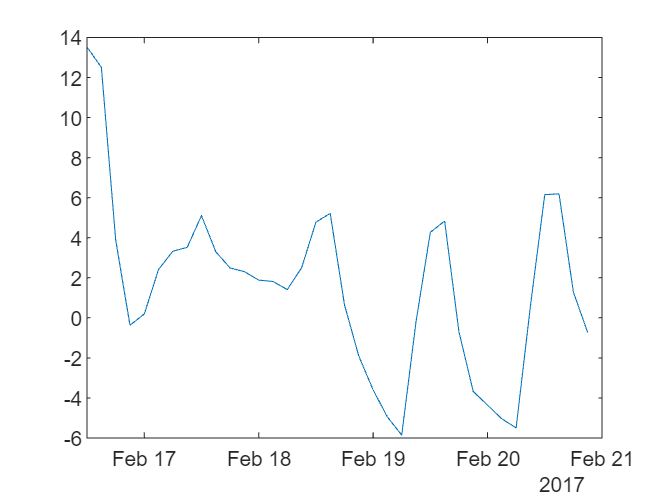

plot(data.date,data.temperature)

## Model 1

n = size(T,1);
x = linspace(1,n,n);
m1 = fitlm(x,T.temperature)

m1 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      5.2087        1.36     3.8299    0.00052575
    x1             -0.19549    0.064099    -3.0497     0.0044166


Number of observations: 36, Error degrees of freedom: 34
Root Mean Squared Error: 4
R-squared: 0.215,  Adjusted R-Squared: 0.192
F-statistic vs. constant model: 9.3, p-value = 0.00442

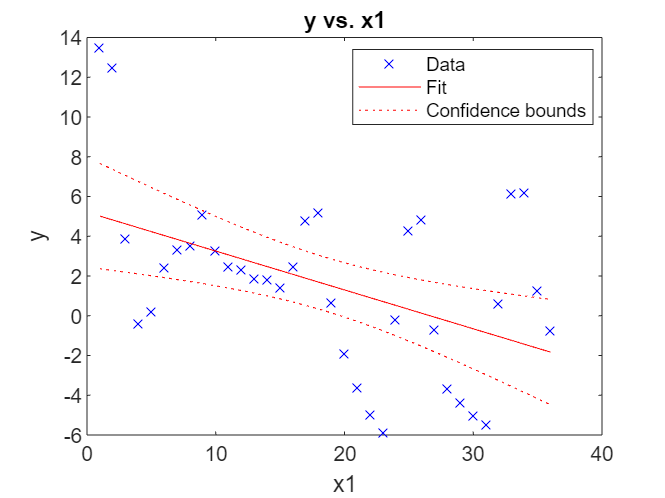

plot(m1)

function forecastData = parseForecast(responseList)
    % Initialize an array of structs to hold the parsed forecast data
    forecastData = struct("date", {}, "temperature", {}, "weather", {}, "clouds", {}, "wind", {}, "details", {});

    % Loop through each entry in the responseList cell array
    for i = 1:length(responseList)
        % Get the current forecast struct
        forecastStruct = responseList{i};

        % Extract the date and time of the forecast
        forecastData(i).date = datetime(forecastStruct.dt, "ConvertFrom", "posixtime");

        % Extract main forecast data like temperature
        forecastData(i).temperature = forecastStruct.main.temp;

        % Extract weather conditions
        forecastData(i).weather = forecastStruct.weather(1).main;

        % Extract cloud data
        forecastData(i).clouds = forecastStruct.clouds.all;

        % Extract wind data
        forecastData(i).wind = forecastStruct.wind.speed;

        % Extract additional details if needed
        forecastData(i).details = forecastStruct.weather(1).description;
    end
end